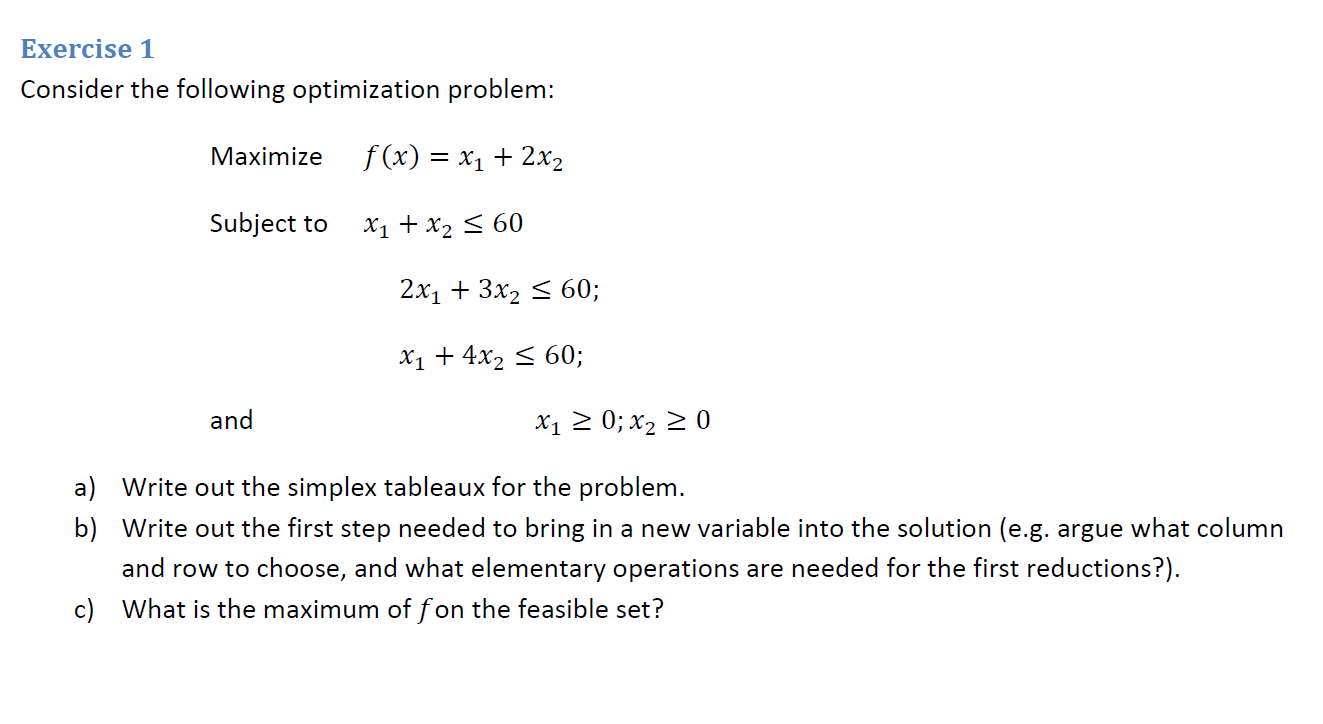

%b
A = [   1 1 1 0 0 0;
        2 3 0 1 0 0;
        1 4 0 0 1 0];
b = [ 60;60;60];
c = -[1;2;0; 0; 0; -1 ];
v = [3;4;5];
simplex(c,A,b,v,1)

 
Initial tableau:
  Column 1

       1       
       2       
       1       
      -1       

  Column 2

       1       
       3       
       4       
      -2       

  Column 3

       1       
       0       
       0       
       0       

  Column 4

       0       
       1       
       0       
       0       

  Column 5

       0       
       0       
       1       
       0       

  Column 6

       0       
       0       
       0       
       1       

  Column 7

      60       
      60       
      60       
       0       

Pivot point:
  Column 1

       3       

  Column 2

       2       

New tableau:
  Column 1

       3/4     
       5/4     
       1/4     
      -1/2     

  Column 2

       0       
       0       
       1       
       0       

  Column 3

       1       
       0       
       0       
       0       

  Column 4

       0       
       1       
       0       
       0       

  Column 5

      -1/4     
      -3/4     
      

ans =       12       
      12       
      36       
       0       
       0       
       0       


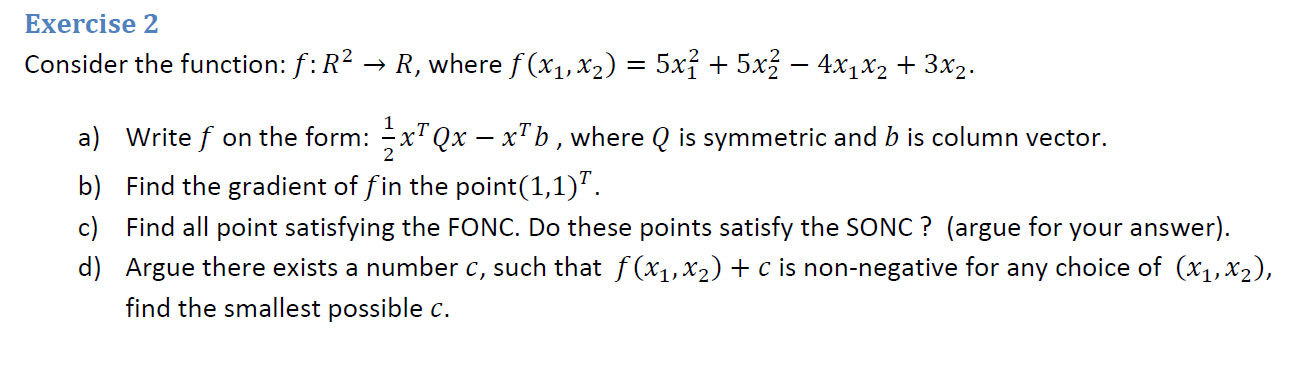

%a
syms x1 x2
f = @(x1,x2) 5*x1^2 + 5*x2^2 - 4*x1*x2 + 3*x2; 
Q = [5 -2;-2 5;];
Q = Q + Q';
b = [0;-3];

fq = @(x) 1/2*x'*Q*x - x'*b

fq = function_handle with value:
    @(x)1/2*x'*Q*x-x'*b



p = [1;1];

%b -  First derivative (gradient)
syms x1 x2
df1_x1 = diff(fq([x1; x2]),x1);
df1_x2 = diff(fq([x1; x2]),x2);
Df = [df1_x1 df1_x2];
gradient = Df'

$$gradient = \left(\begin{array}{c} 5\,x_{1}-2\,x_{2}+5\,\bar{x_{1}}-2\,\bar{x_{2}}\\ 5\,x_{2}-2\,x_{1}-2\,\bar{x_{1}}+5\,\bar{x_{2}}+3 \end{array}\right)$$

gf = matlabFunction(gradient);
gf(1,1)

ans =        6       
       9       



%c
%fonc
syms x1 x2
eqns = [gf(x1,x2)==0,x1~=0, x2~=0];
sol = solve(eqns,x1,x2,'Real',true);
x = [sol.x1'; sol.x2']

$$x = \left(\begin{array}{c} -\frac{1}{7}\\ -\frac{5}{14} \end{array}\right)$$


%sonc
syms x1 x2
df2_x1_x1 = diff(fq([x1;x2]),x1,x1);
df2_x1_x2 = diff(fq([x1;x2]),x1,x2);
df2_x2_x1 = diff(fq([x1;x2]),x2,x1);
df2_x2_x2 = diff(fq([x1;x2]),x2,x2);
D2f = [df2_x1_x1 df2_x2_x1; df2_x1_x2 df2_x2_x2]

$$D2f = \left(\begin{array}{cc} 10 & -4\\ -4 & 10 \end{array}\right)$$

det(D2f)

$$ans = 84$$

[V,D] = eig(D2f); %D gives eigen values
D

$$D = \left(\begin{array}{cc} 6 & 0\\ 0 & 14 \end{array}\right)$$


% Both positive - positive definite
% one positive one negative - indefinite
% one of them negative and one zero - negative semi definite
% both negative - negative definite

## d)

The point $\overline{x} =\left\lbrack \begin{array}{c}
-\frac{1}{7}\\
-\frac{5}{14}
\end{array}\right\rbrack$has been determined to be minimizer. This implies that there is a lower limit on the value $f\left(x_1 ,x_2 \right)$ can assume. The lower limit means there must exist a *c*, which ensures that $f\left(x_1 ,x_2 \right)+c\ge 0$.

To ensure that $f\left(x_1 ,x_2 \right)+c\ge 0$, *c* must assume the negative value of the function in the minimum:


$$c=-f\left(\left\lbrack \begin{array}{c}
-\frac{1}{7}\\
-\frac{5}{14}
\end{array}\right\rbrack \right)=\frac{15}{28}=0\ldotp 5357$$


c = -fq([x(1);x(2)])

$$c = \frac{15}{28}$$

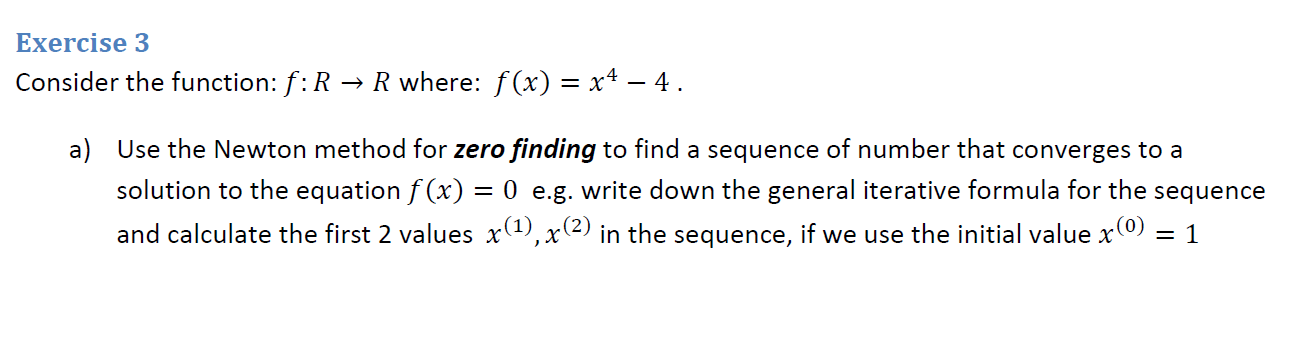

syms x
f = @(x) x^4 -4

f = function_handle with value:
    @(x)x^4-4


gradient = diff(f,x)

$$gradient = 4\,x^{3}$$

gradient = matlabFunction(gradient)

gradient = function_handle with value:
    @(x)x.^3.*4.0


D2f = diff(f,x,x)

$$D2f = 12\,x^{2}$$

F = matlabFunction(D2f)

F = function_handle with value:
    @(x)x.^2.*1.2e+1


x0 = 1;

Applying two iterations of Newton's method:

N = 2 % iterations

N =        2       


x = zeros(1,N)

x =        0              0       


x(1,:) = x0;

for i=1:N
    g = gradient(x(i,1));
    x(i+1,:) = x(i,:)'-F(x(i,1))^-1*g;
end
x

x =        1              1       
       2/3            2/3     
       4/9            4/9     


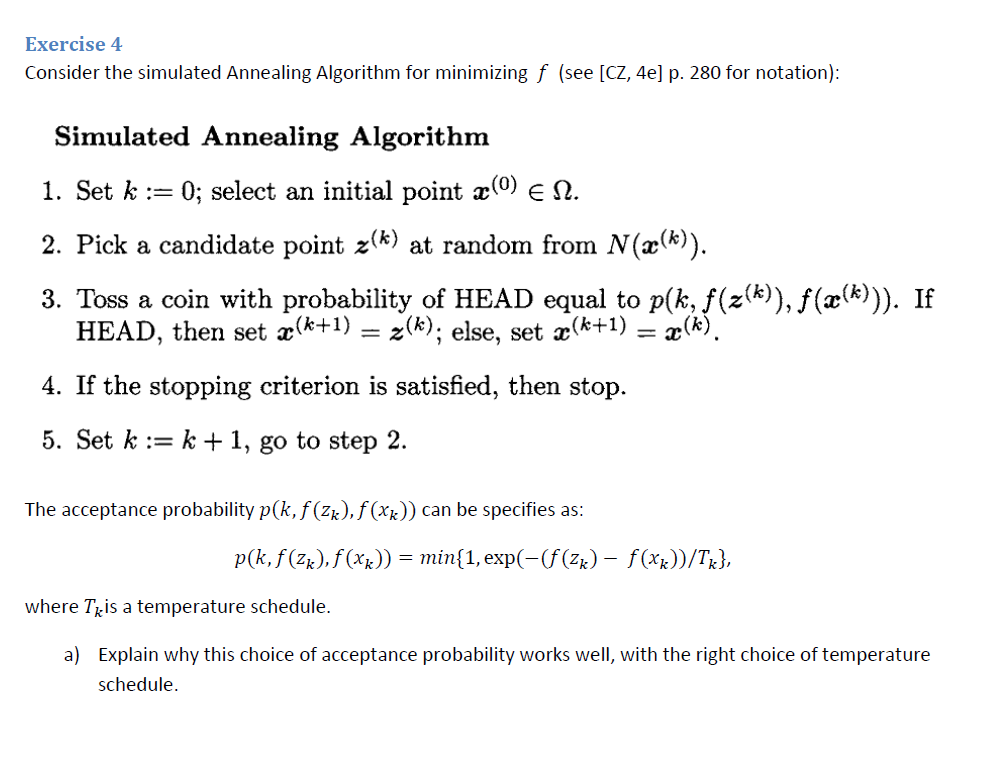

lower_bound = -3;
upper_bound = 3;
res = .1;
[x, y] = meshgrid(lower_bound:res:upper_bound,lower_bound:res:upper_bound);

gamma = 0.9;

The cooling schedule is then:

T_k = @(g,k) g/log(k+2);

The probability of selecting an inferior point is given by:

pr = @(z,x,temp) exp(-(f(z(1),z(2))-f(x(1),x(2)))/temp);

***Step 1:***

An initial point is selected:

k = 0;

% randomized index of x range
[m, n] = size(x);
x = x(1,randi(m));

% randomized index of y range
[m, n] = size(y);
y = y(randi(m),1);

% randomly selected point
x_k = [x; y];
x_best = x_k;

% point evaluation
min = f(x_k(1),x_k(2));

Error using Exam2015>@(x)x^4-4
Too many input arguments.


iteration_limit = 150;
for i=0:iteration_limit
    k = i;
    
    % Step 2: Pick Neighborhood point
    x_cur = rp(x_k(1),alpha);
    y_cur = rp(x_k(2),alpha);
    
    % Constrain values of x and y to the bounds of the function
    if (x_cur < lower_bound)
        x_cur = lower_bound;
    elseif (x_cur > upper_bound)
        x_cur = upper_bound;
    end
    
    if (y_cur < lower_bound)
        y_cur = lower_bound;
    elseif (y_cur > upper_bound)
        y_cur = upper_bound;
    end
    f_cur = f(x_cur,y_cur);
    
    % Step 3: Evaluate selected point using temperature
    temp = T_k(gamma,k);
    prob = pr(x_k,[x_cur; y_cur],temp);
    cointoss = rand(1);
    if cointoss <= prob
        x_k = [x_cur; y_cur];        
    end
    
    % Keep track of the best point found
    if(f_cur < min)
        min = f_cur;
        x_best = [x_cur; y_cur];
        h_anneal_best = scatter3(x_best(1), x_best(2), min, '*r'); 
    end
    
    % Plot current iteration point
    f_k = f(x_k(1),x_k(2));
    h_anneal = scatter3(x_k(1), x_k(2), f_k, '.r');
    
end
rotate3d on
legend([h_naive h_anneal h_anneal_best],{'Naive Random Search','Simulated Annealing','Simulated Annealing Bests'})
title('Ex 14.2: Naive Random Search & Simulated Annealing')
hold off

disp('Simulated Annealing')
fprintf('Iterations: %d\n',iteration_limit);
fprintf('Minimum found %f at (x,y)=(%f,%f)',min,x_best(1),x_best(2));

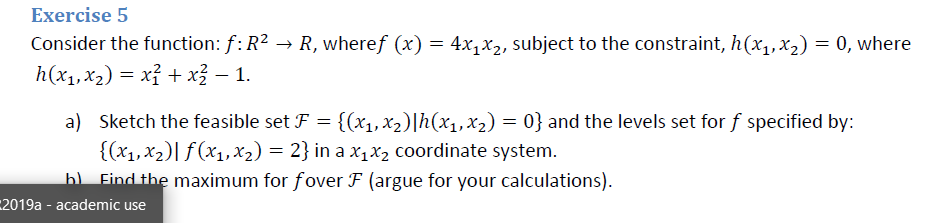

syms x1 x2
x = [x1; x2];
f = @(x1,x2) 4*x1*x2;
h = @(x1,x2) x1.^2 + x2.^2 - 1;

syms lambda
l = f(x1,x2)+lambda*h

$$l = 4\,x_{1}\,x_{2}+\lambda \,\left({x_{1}}^{2}+{x_{2}}^{2}-1\right)$$


dlx1 = diff(l,x1)

$$dlx1 = 4\,x_{2}+2\,\lambda \,x_{1}$$

dlx2 = diff(l,x2)

$$dlx2 = 4\,x_{1}+2\,\lambda \,x_{2}$$

dll = diff(l,lambda)

$$dll = {x_{1}}^{2}+{x_{2}}^{2}-1$$


syms x1 x2 lambda
[x1, x2, lambda] = solve(dlx1==0,dlx2==0,dll==0, x1, x2, lambda)

$$x1 = \left(\begin{array}{c} -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2}\\ -\frac{\sqrt{2}}{2} \end{array}\right)$$

$$x2 = \left(\begin{array}{c} -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2}\\ -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} \end{array}\right)$$

$$lambda = \left(\begin{array}{c} -2\\ -2\\ 2\\ 2 \end{array}\right)$$


x1 = [-sqrt(2)/2; -sqrt(2)/2];
x2 = [sqrt(2)/2; sqrt(2)/2];
x3 = [sqrt(2)/2; -sqrt(2)/2];
x4 = [-sqrt(2)/2; -sqrt(2)/2];

f(x1(1),x1(2))

ans =        2       


f(x2(1),x2(2))

ans =        2       


f(x3(1),x3(2))

ans =       -2       


f(x4(1),x4(2))

ans =        2       


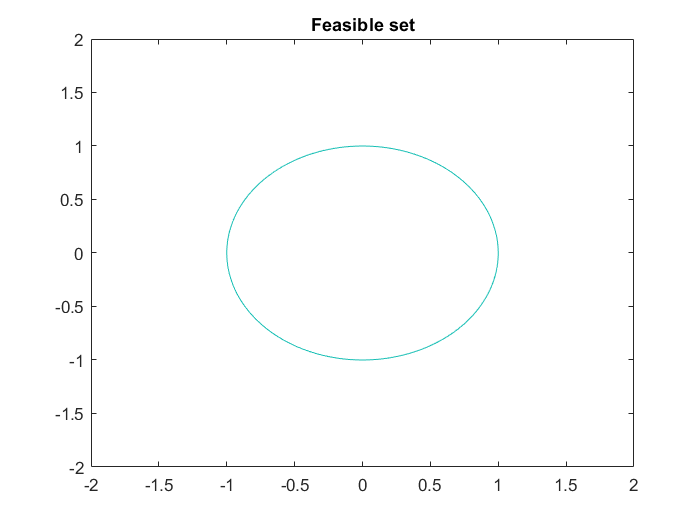




% FEASIBLE SET
x1 = linspace(-2,2);
x2 = linspace(-2,2);
[X1,X2] = meshgrid(x1,x2);
figure
xlabel('x_1')
ylabel('x_2')
contour(X1,X2,h(X1,X2),[0,0])
title('Feasible set')



% LEVEL SET
zhandle = fcontour(f)

zhandle =   FunctionContour with properties:

     Function: @(x1,x2)4*x1*x2
    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 1/2
         Fill: 'off'
    LevelList: [-80 -60 -40 -20 0 20 40 60 80 100]

  Show all properties


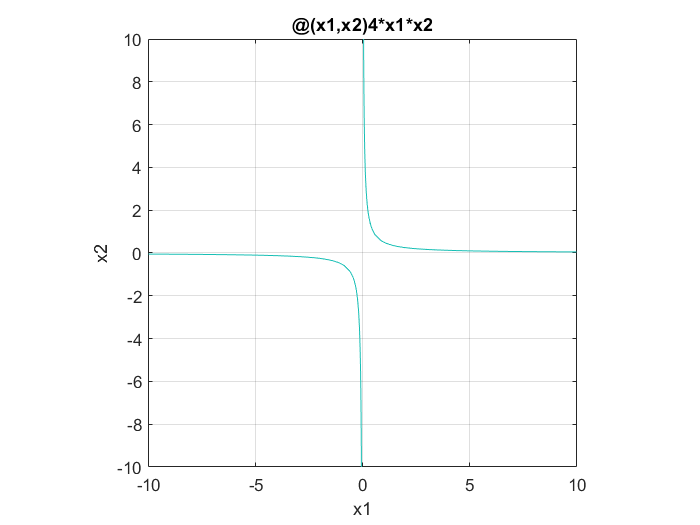

zhandle.LevelList = [2];
xlabel x1
ylabel x2
title(func2str(f))
grid on
zhandle.YRange = [-10,10];
zhandle.XRange = [-10,10];
axis equal